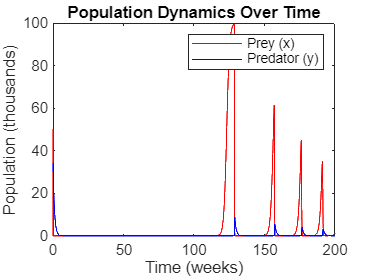

% Parameters
r_x = 1; K_x = 100; alpha = 2.5; beta = 0.25; r_y = -1;
x0 = 50; y0 = 30; % Initial populations
t_stop = 200; dt = 0.01; % Time parameters

% Time vector
t = 0:dt:t_stop;
n_steps = length(t);

% Initialize population vectors
x = zeros(1, n_steps);
y = zeros(1, n_steps);
x(1) = x0; y(1) = y0;

% Euler method
for i = 1:n_steps-1
    dx_dt = x(i) * (r_x - r_x * x(i) / K_x) - alpha * x(i) * y(i);
    dy_dt = y(i) * (beta * x(i) + r_y);
    x(i+1) = x(i) + dx_dt * dt;
    y(i+1) = y(i) + dy_dt * dt;
end

% Plot populations over time
figure;
plot(t, x, 'r', 'DisplayName', 'Prey (x)');
hold on;
plot(t, y, 'b', 'DisplayName', 'Predator (y)');
title('Population Dynamics Over Time');
xlabel('Time (weeks)');
ylabel('Population (thousands)');
legend;

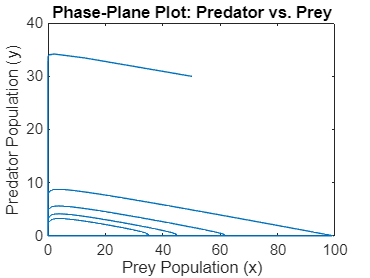


% Phase-plane plots
figure;
plot(x, y);
title('Phase-Plane Plot: Predator vs. Prey');
xlabel('Prey Population (x)');
ylabel('Predator Population (y)');

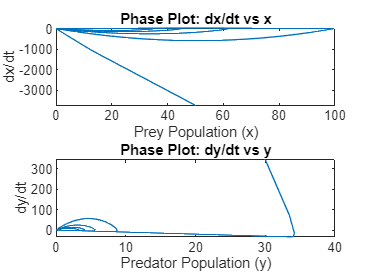


% Phase plots for dx vs x and dy vs y
figure;
subplot(2,1,1);
plot(x, diff([x 0]) / dt);
title('Phase Plot: dx/dt vs x');
xlabel('Prey Population (x)');
ylabel('dx/dt');

subplot(2,1,2);
plot(y, diff([y 0]) / dt);
title('Phase Plot: dy/dt vs y');
xlabel('Predator Population (y)');
ylabel('dy/dt');